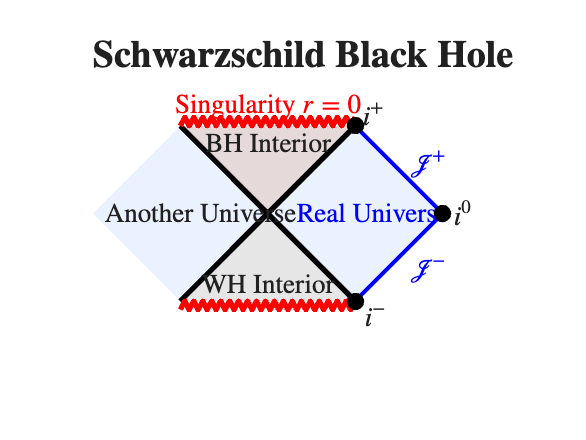

% PENROSE_DIAGRAMS
close all; clc;

%参考ai学习部署latex,可以打出特殊符号
set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultAxesFontSize', 14);

%  史瓦西黑洞 
figure('Name', 'Schwarzschild Direct', 'Color', 'w', 'Position', [100, 100, 800, 600]);
hold on; axis equal; axis off;
xlim([-2.5, 3.0]); ylim([-1.5, 1.5]);

% 定义颜色 
col_I   = [0.92, 0.95, 1.0]; % 外部区域
col_II  = [0.9, 0.85, 0.85]; % 黑洞内部
col_III = [0.9, 0.9, 0.9];   % 白洞内部
col_IV  = [0.92, 0.95, 1.0]; % 平行宇宙

% 绘制区域 
fill([0, 1, 2, 1], [0, 1, 0, -1], col_I, 'EdgeColor', 'none');
fill([0, -1, -2, -1], [0, 1, 0, -1], col_IV, 'EdgeColor', 'none');
fill([0, 1, -1], [0, 1, 1], col_II, 'EdgeColor', 'none');
fill([0, 1, -1], [0, -1, -1], col_III, 'EdgeColor', 'none');

% 绘制边界线 
plot([-1, 1], [-1, 1], 'k-', 'LineWidth', 2); % H+
plot([-1, 1], [1, -1], 'k-', 'LineWidth', 2); % H-
plot([1, 2], [1, 0], 'b-', 'LineWidth', 1.5); % Scri+
plot([1, 2], [-1, 0], 'b-', 'LineWidth', 1.5); % Scri-

% 1. 未来奇点
x_zig1 = linspace(-1, 1, 40);       
amp = 0.05;                         % 锯齿振幅
y_zig1 = 1.05 + amp * (-1).^(1:length(x_zig1));
plot(x_zig1, y_zig1, 'r', 'LineWidth', 2);

% 2. 过去奇点
x_zig2 = linspace(-1, 1, 40);
y_zig2 = -1.05 + amp * (-1).^(1:length(x_zig2));
plot(x_zig2, y_zig2, 'r', 'LineWidth', 2);

% 标注文字 
text(0.3, 0, 'Real Universe', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'b');
text(-1.9, 0, 'Another Universe', 'FontSize', 10, 'FontWeight', 'bold');
text(0, 0.8, 'BH Interior', 'FontSize', 10, 'HorizontalAlignment', 'center');
text(0, -0.8, 'WH Interior', 'FontSize', 10, 'HorizontalAlignment', 'center');

% 时空的边界点 
plot(2, 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6);
plot(1, 1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6);
plot(1, -1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6);

% 绘制LaTeX标签 
text(2.1, 0, '$i^0$', 'HorizontalAlignment', 'left'); 
text(1.2, 1.15, '$i^+$', 'HorizontalAlignment', 'center'); 
text(1.23, -1.15, '$i^-$', 'HorizontalAlignment', 'center'); 
text(1.6, 0.6, '$\mathcal{J}^+$', 'Color', 'b'); 
text(1.6, -0.6, '$\mathcal{J}^-$', 'Color', 'b'); 
text(0, 1.25, 'Singularity $r=0$', 'Color', 'r', 'HorizontalAlignment', 'center');
title('\textbf{Schwarzschild Black Hole}');

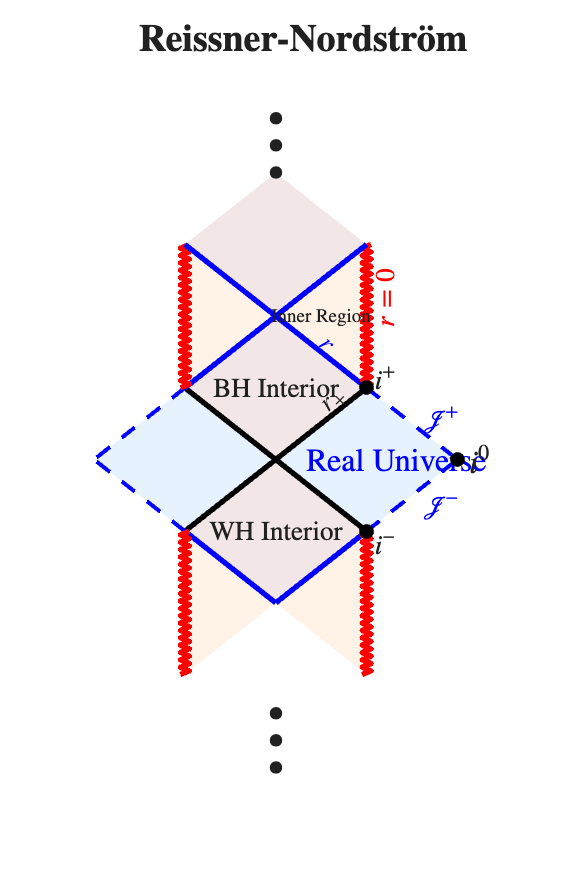



%  RN黑洞
figure('Name', 'RN Direct', 'Color', 'w', 'Position', [950, 50, 600, 900]);
hold on; axis off;
axis([-2.2 2.8 -4.5 5.5]);

% 颜色 
c_out = [0.9, 0.95, 1];   
c_bh  = [0.95, 0.9, 0.9]; 
c_in  = [1, 0.95, 0.9];   

% 绘制中心区块
fill([0, 1, 0, -1], [0, 1, 2, 1], c_bh, 'EdgeColor', 'none');     
fill([0, 1, 2, 1], [0, 1, 0, -1], c_out, 'EdgeColor', 'none');    
fill([0, -1, -2, -1], [0, 1, 0, -1], c_out, 'EdgeColor', 'none'); 
fill([0, 1, 0, -1], [0, -1, -2, -1], c_bh, 'EdgeColor', 'none');  

% 线条
plot([0, 1], [0, 1], 'k-', 'LineWidth', 2);  
plot([0, -1], [0, 1], 'k-', 'LineWidth', 2); 
plot([0, 1], [0, -1], 'k-', 'LineWidth', 2); 
plot([0, -1], [0, -1], 'k-', 'LineWidth', 2);
plot([1, 2], [1, 0], 'b--', 'LineWidth', 1.5); 
plot([1, 2], [-1, 0], 'b--', 'LineWidth', 1.5); 
plot([-1, -2], [1, 0], 'b--', 'LineWidth', 1.5);
plot([-1, -2], [-1, 0], 'b--', 'LineWidth', 1.5);

% 未来延拓区域
fill([-1, 0, -1], [1, 2, 3], c_in, 'EdgeColor', 'none'); 
fill([1, 0, 1], [1, 2, 3], c_in, 'EdgeColor', 'none');   
plot([0, 1], [2, 1], 'b-', 'LineWidth', 2); 
plot([0, -1], [2, 1], 'b-', 'LineWidth', 2);

% 左奇点 
y_v1 = linspace(1, 3, 40);
x_v1 = -1 + 0.05 * (-1).^(1:length(y_v1));
plot(x_v1, y_v1, 'r', 'LineWidth', 2);

% 右奇点
y_v2 = linspace(1, 3, 40);
x_v2 = 1 + 0.05 * (-1).^(1:length(y_v2));
plot(x_v2, y_v2, 'r', 'LineWidth', 2);

% 宇宙延拓 
fill([0, 1, 0, -1], [2, 3, 4, 3], c_bh, 'EdgeColor', 'none'); 
plot([0, 1], [2, 3], 'b-', 'LineWidth', 2); 
plot([0, -1], [2, 3], 'b-', 'LineWidth', 2);

% 过去延拓区域
fill([-1, 0, -1], [-1, -2, -3], c_in, 'EdgeColor', 'none');
fill([1, 0, 1], [-1, -2, -3], c_in, 'EdgeColor', 'none');
plot([0, 1], [-2, -1], 'b-', 'LineWidth', 2); 
plot([0, -1], [-2, -1], 'b-', 'LineWidth', 2);

% 左侧过去奇点
y_v3 = linspace(-3, -1, 40);
x_v3 = -1 + 0.05 * (-1).^(1:length(y_v3));
plot(x_v3, y_v3, 'r', 'LineWidth', 2);

% 右侧过去奇点
y_v4 = linspace(-3, -1, 40);
x_v4 = 1 + 0.05 * (-1).^(1:length(y_v4));
plot(x_v4, y_v4, 'r', 'LineWidth', 2);

% 区域标注
text(0.3, 0, 'Real Universe', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'b');
text(0, 1, 'BH Interior', 'HorizontalAlignment', 'center');
text(0, -1, 'WH Interior', 'HorizontalAlignment', 'center');
text(0.5,2,'Inner Region','FontSize', 7, 'HorizontalAlignment', 'center')
    
plot(2, 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5);    
plot(1, 1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5);    
plot(1, -1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5);   

text(2.1, 0, '$i^0$', 'FontSize', 12, 'HorizontalAlignment', 'left');
text(1.2, 1.15, '$i^+$', 'HorizontalAlignment', 'center'); 
text(1.2, -1.15, '$i^-$', 'HorizontalAlignment', 'center');
text(1.6, 0.6, '$\mathcal{J}^+$', 'Color', 'b'); 
text(1.6, -0.6, '$\mathcal{J}^-$', 'Color', 'b');

text(0, 4.5, '$\vdots$', 'FontSize', 35, 'HorizontalAlignment', 'center');
text(0, -3.8, '$\vdots$', 'FontSize', 35, 'HorizontalAlignment', 'center');
text(0.5, 0.7, '$r_+$', 'Rotation', 45);            
text(0.5, 1.7, '$r_-$', 'Rotation', -45, 'Color', 'b'); 
text(1.2, 1.8, '$r=0$', 'Rotation', 90, 'Color', 'r');  

title('\textbf{Reissner-Nordstr\"om}');